# How bad is the prediction if a method scores a cell with 0?

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Often there could be a score of 0 for a particular cell, by some method. If we look at these observations (method-specific), can we use the ground truth to estimate how bad it is to have a 0 score?

DETAIL: For many methods while going through the numerical procedures, we were categorical about avoiding "divide by 0". If such a situation arised, we insisted on bypassing the rest of the steps, and simply scoring the cell with a 0 (method specific). Now, if by some method, a cell is given a score of 0, how likely is it to actually be a time cell?

close all
%clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1;

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0;
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end


% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Synthetic Dataset Details
input.gDate = 20210824; %generation date
input.gRun = 1; %generation run number
input.nDatasets = 333;

% Consolidated Analysis Details
input.cDate = 20210918; %consolidation date
input.cRun = 1; %consolidation run number

workingOnServer = 0;
diaryOn         = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')
synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')
% Load Analysis Results
disp('Loading analysis results ...')
analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

input.removeNaNs = 0;
input.saveFolder = saveFolder;


%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

%Normalize
maxima = max(predictor);
normPredictor = predictor./maxima;

%Z-Score
zPredictor = zscore(predictor);

% Normalize Z-Score - unlikely to be helpful, but an option nonetheless
maxima = max(zPredictor);
nzPredictor = zPredictor./maxima;

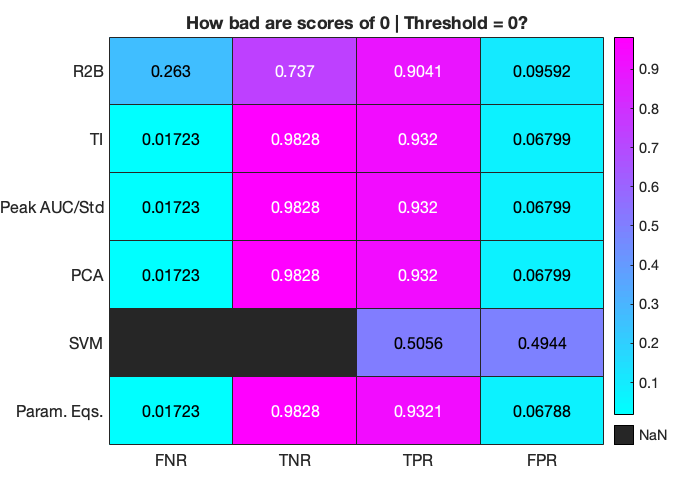

nObs = size(predictor, 1);
v = 1:nObs;

rFN = zeros(input.nMethods, 1);
rTN = zeros(input.nMethods, 1);

rTP = zeros(input.nMethods, 1);
rFP = zeros(input.nMethods, 1);

for method = 1:input.nMethods
    iZeroScores = v; %preallocation, will prune
    iProperScores = find(predictor(:, method));
    iZeroScores(iProperScores) = [];
    
    % Now we find the False Negatives and True Negatives considering the 0s
    rFN(method) = length(find(response(iZeroScores)))/length(iZeroScores);
    rTN(method) = 1 - rFN(method);
    
    % Now we find the False Positives and True Positives considering the non-0s
    rTP(method) = length(find(response(iProperScores)))/length(iProperScores);
    rFP(method) = 1 - rTP(method);
end

bundledResults = [rFN, rTN, rTP, rFP];

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Labels
methodLabels = {'R2B', 'TI', 'Peak AUC/Std', 'PCA', 'SVM', 'Param. Eqs.'};
methodLabels2 = {'A', 'B', 'C', 'D', 'E', 'F'};
confMatLabels = {'FNR', 'TNR', 'TPR', 'FPR'};

fig1 = figure(1);
clf
set(fig1, 'Position', [100, 100, 700, 500])
h = heatmap(bundledResults, ...
    'Colormap', cool, ...
    'Title', 'How bad are scores of 0 | Threshold = 0?');
h.XDisplayLabels = confMatLabels;
h.YDisplayLabels = methodLabels;
set(gca, 'FontSize', figureDetails.fontSize)